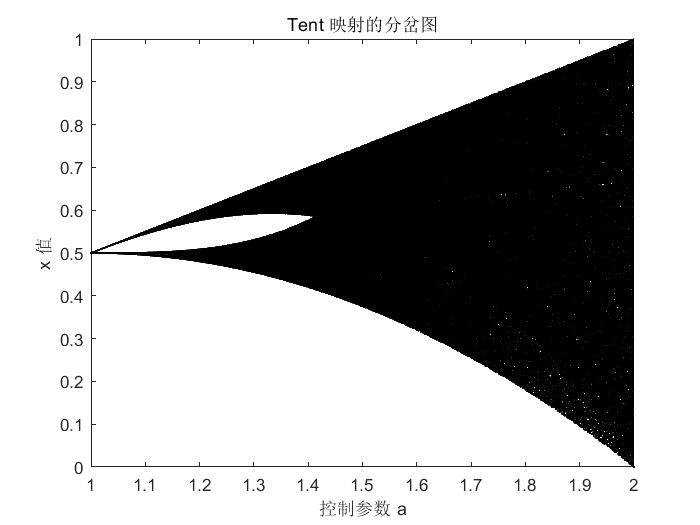

% Tent 映射的分岔图
% 参数设置
a_min = 1;       % 控制参数 a 的最小值
a_max = 2;       % 控制参数 a 的最大值
num_a = 1000;    % a 的采样点数量
N = 1000;        % 总迭代次数
nSkip = 500;     % 跳过前 nSkip 次迭代，以排除初始条件的影响

% 初始化 a 的值和保存分岔图的 x 值
a_values = linspace(a_min, a_max, num_a); % a 从 a_min 到 a_max 的采样点
x_vals = zeros(num_a, N - nSkip);         % 存储分岔图中的 x 值

% 遍历每个 a 值，计算对应的 Tent 映射
for i = 1:num_a
    a = a_values(i);   % 当前 a 值
    x = 0.5;           % 初始条件
    
    % 进行 N 次迭代
    for n = 1:N
        if x < 0.5
            x = a * x;            % Tent 映射公式（x < 0.5 时）
        else
            x = a * (1 - x);      % Tent 映射公式（x >= 0.5 时）
        end
        
        % 跳过前 nSkip 次迭代，保存后续的值
        if n > nSkip
            x_vals(i, n - nSkip) = x;
        end
    end
end

% 绘制分岔图
figure;
plot(a_values, x_vals, '.k', 'MarkerSize', 0.1);
xlabel('控制参数 a');ylabel('x 值');title('Tent 映射的分岔图');
axis([a_min, a_max, 0, 1]);